close all
clear

load ws_steak.mat

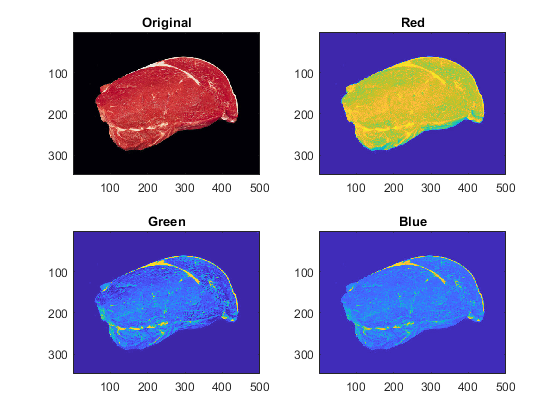

s1=imread('steak01.jpg');
s2=imread('steak02.jpg');

s1_unf= double(reshape(s1,348*500,3));
s2_unf = double(reshape(s2,341*431,3));

figure
for i=0:3
    subplot(2,2,i+1)
    if i == 0
        imagesc(s1)
        title("Original")
    else
        imagesc(s1(:,:,i))
        if i == 1
            title("Red")
        elseif i == 2
            title("Green")
        else
            title("Blue")
        end
    end
end

evaSqEuclidean = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattan = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
evaSqEuclideanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
eva_t = [evaSqEuclidean.CriterionValues, evaManhattan.CriterionValues, evaSqEuclideanAutoscale.CriterionValues, evaManhattanAutoscale.CriterionValues];

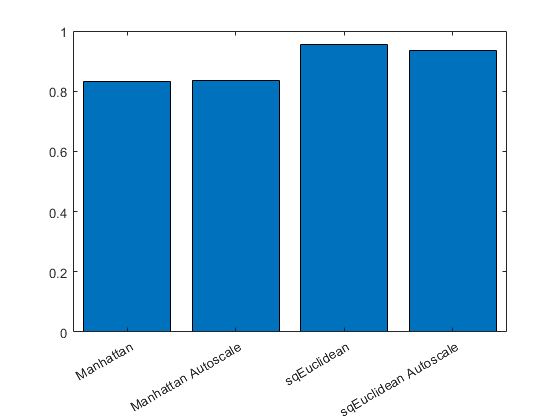

name = categorical({'sqEuclidean';'Manhattan'; 'sqEuclidean Autoscale'; 'Manhattan Autoscale'}); 
figure
bar(name,eva_t)

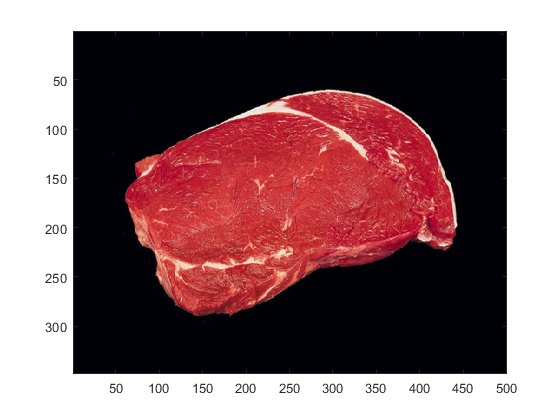

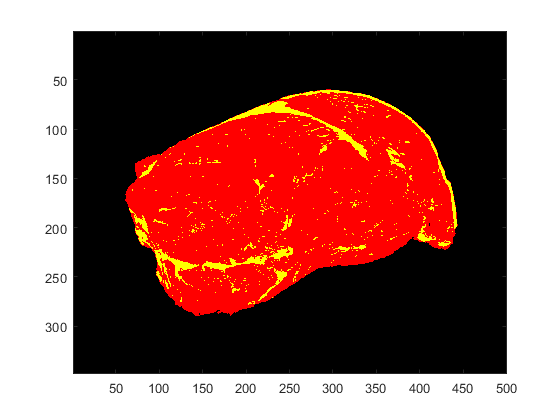

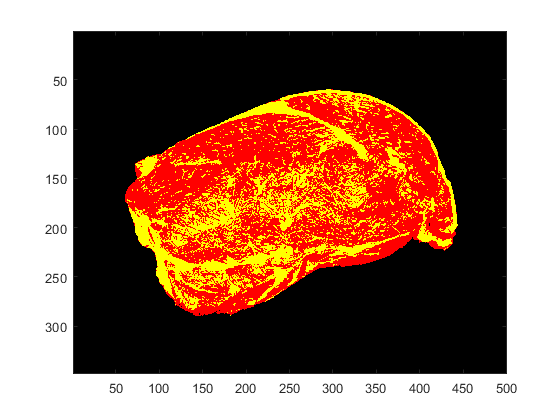

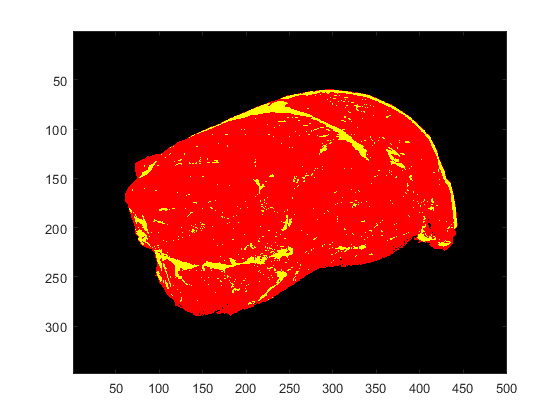

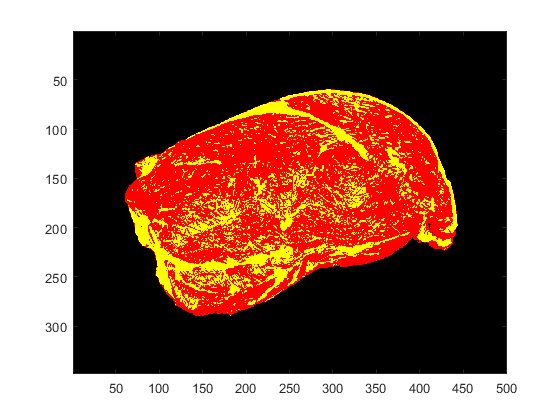

KMeans